clc
clear
close all




spreadMetric = 9; % Radius of spreading edges 
blendRadius = 9; % Radius of fading on segment borders
modeFilterWidth = 15; % Segmentation map filtering 
sensitivity = 2.5; %(1-4) Higher=less noise robustness
saveOnlyOutput = false;
saveGIF = true;
imPathVect = ["SortedPhotos\5\"]; %Folder to work with
outputPathVect = ["5\"];
outputNameVect = ["5"];
for reps = 1:length(imPathVect)
imPath = imPathVect(reps); %Folder to work with
outputPath = outputPathVect(reps);
outputName = outputNameVect(reps);

Prepare filepaths

imList = dir(imPath);
imPaths = repmat("",length(imList),1);
dirs = zeros([length(imList) 1],"logical");
for i = 1:length(imList)
    dirs(i) = imList(i).isdir;
    imPaths(i) = strcat(imPath,imList(i).name);
end
imPaths(dirs) = [];
if (~exist(outputPath, 'dir')); mkdir(outputPath); end

Read images and perform scale correction

figure(1)
wb = waitbar(0,"Reading and reducing images");
sz = size(imread(imPaths(1)));
if length(sz) == 2
    sz(3) = 1;
end
sz(4) = length(imPaths);
imgRaw = zeros(sz,'uint8');
imgIn = zeros([sz(1:2)*0.25 1 sz(4)],'uint8');
for i = 1:sz(4)
    imgRaw(:,:,:,i) = imread(imPaths(i));
    
    if sz(3) == 3
        imgIn(:,:,:,i) = rgb2gray(imresize(imgRaw(:,:,:,i),0.25));
    else
        imgIn(:,:,:,i) = imresize(imgRaw(:,:,:,i),0.25);
    end
    waitbar(i/sz(4),wb)
end


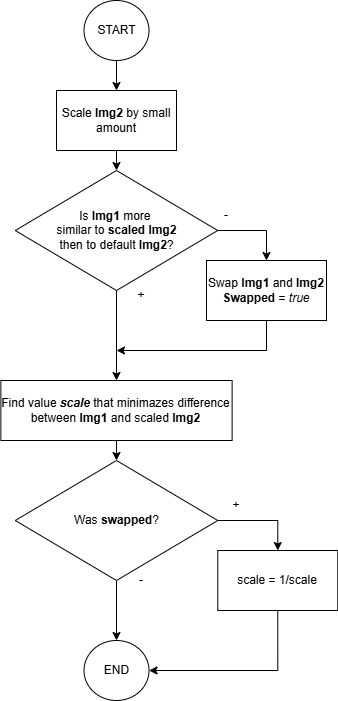

Find scales

smallest = 1; %index of img with scale = 1
scales = ones([sz(4) 1]); %resulting array
for i = 2:sz(4)
    waitbar(i/sz(4),wb,"Finding scale values")
    img1 = imgIn(:,:,:,smallest);
    img2 = imgIn(:,:,:,i);
    scaleSmall = 1.001; 
    swapped = false;
    diff0 = ImageDifference(img1,img2);
    img2scaled = ImageCropCentered(img2,scaleSmall);
    diff1 = ImageDifference(img1,img2scaled);
    if diff0 < diff1
        [img1, img2] = Swap(img1,img2);
        swapped = true;
        smallest = i;
    end
    fun = @(scale)ImageDifference(img1,ImageCropCentered(img2,scale));
    scale = fminbnd(fun,1,1.15,optimset("TolX",4e-4));
    if swapped == true
        scales = scales * scale;
        scales(i) = 1;
    else
        scales(i) = scale;
    end
end
for i = 1:sz(4)
    waitbar(i/sz(4),wb,"Rescaling images")
    imgRaw(:,:,:,i) = ImageCropCentered(imgRaw(:,:,:,i),scales(i));
end

Find gradient using Laplacian of Gaussian, then spread using averaging circle mask

waitbar(i/sz(4),wb,"Calculating metrics")
imgWeight = zeros([sz([1 2])/2 sz(4)]);
for i = 1:sz(4)
    if sz(3) == 3
        imgReduced = impyramid(rgb2gray(imgRaw(:,:,:,i)),'reduce');
    else
        imgReduced = impyramid(imgRaw(:,:,1,i),'reduce');
    end
    imgReduced = padarray(imgReduced,[3 3],"replicate","both");
    imgFlt = conv2(imgReduced,fspecial("log",7,0.8),"valid").^2;
    imgWeight(:,:,i) = conv2(imgFlt,fspecial("disk",spreadMetric),"same");
    % imgWeight(:,:,i) = imgFlt;
    waitbar(i/sz(4),wb,"Calculating metrics")
end

Make segmentation map and create output image

% threshold = 100;

waitbar(0,wb,"Finding best pixels and filtering")
threshold = mean(imgWeight,"all")/sensitivity;
imgWeight(:,:,sz(4)+1) = threshold*ones(size(imgFlt)); 

%Find maximums of metrics
[~, indexes] = max(imgWeight,[],3);
indexFiltered = modefilt(indexes,[modeFilterWidth modeFilterWidth],"symmetric");
% indexFiltered = imopen(indexFiltered,strel("disk",9));
% indexFiltered = imclose(indexFiltered,strel("disk",9));
indexBeforeGrowing = indexFiltered;
indexBeforeGrowing(indexBeforeGrowing == sz(4)+1) = 0;
indexBest = bwgrowregions(indexBeforeGrowing,"chessboard");
indexBest = imresize(indexBest,2,"nearest");

blendFilter = fspecial("disk",blendRadius);
imgOut = zeros(sz(1:3),"uint8");
% Copy not blended regions
for i = 1:sz(4)
        segBlend = imfilter(double(indexBest == i),blendFilter);
        segMap3 = repmat(segBlend,[1 1 sz(3)]);
        imgOut = imgOut + uint8(double(imgRaw(:,:,:,i)).*segMap3);
end

Saving results and mid products

waitbar(0,wb,"Saving Images")
segColorMap = [jet(sz(4)); 0 0 0];
outputName = strcat(outputPath,outputName);
imwrite(imgOut,strcat(outputName,"-Output.jpg"),"jpg","Quality",95);
if saveOnlyOutput == false
    imwrite(indexes,segColorMap,strcat(outputName,"-Indexes.png"),"png");
    imwrite(indexFiltered,segColorMap,strcat(outputName,"-IndexesFiltered.png"),"png");
    imwrite(indexBest,segColorMap,strcat(outputName,"-IndexesOut.png"),"png");
    if saveGIF == true
        low = min(imgWeight(:,:,i),[],"all");
        % high = max(imgWeight(:,:,i),[],"all");
        high = threshold;
        imgWeightScaled = uint8((imresize(imgWeight,0.5) - low)*(256/(high-low)));
        for i = 1:sz(4)           
            if i == 1
                [I,map] = gray2ind(imgWeightScaled(:,:,i),256);
                imwrite(I,map,strcat(outputName,"-Weights.gif"),"gif",LoopCount=Inf,DelayTime=1);
            else
                I = gray2ind(imgWeightScaled(:,:,i),256);
                imwrite(I,map,strcat(outputName,"-Weights.gif"),"gif",WriteMode="append",DelayTime=1);
            end
        end
        imgRawScaled = imresize(imgRaw,0.25);
        for i = 1:sz(4)           
            if i == 1
                [I,map] = rgb2ind(imgRawScaled(:,:,:,i),256);
                imwrite(I,map,strcat(outputName,"-ScaleCorrected.gif"),"gif",LoopCount=Inf,DelayTime=1);
            else
                I = rgb2ind(imgRawScaled(:,:,:,i),map);
                imwrite(I,map,strcat(outputName,"-ScaleCorrected.gif"),"gif",WriteMode="append",DelayTime=1);
            end
        end
    end
end
close(wb)
end

Function definitions

function I = ImageCropCentered(I,scale)
    Iscaled = imresize(I,floor(size(I(:,:,1))*scale),"nearest");
    I = imcrop(Iscaled,centerCropWindow2d(size(Iscaled(:,:,1)),size(I(:,:,1))));
end

function score = ImageDifference(I1,I2)
    score = sum((int16(I1(:))-int16(I2(:))).^2,"all");
end

function [b,a] = Swap(a,b)
end